LF Glottal Source Modeling

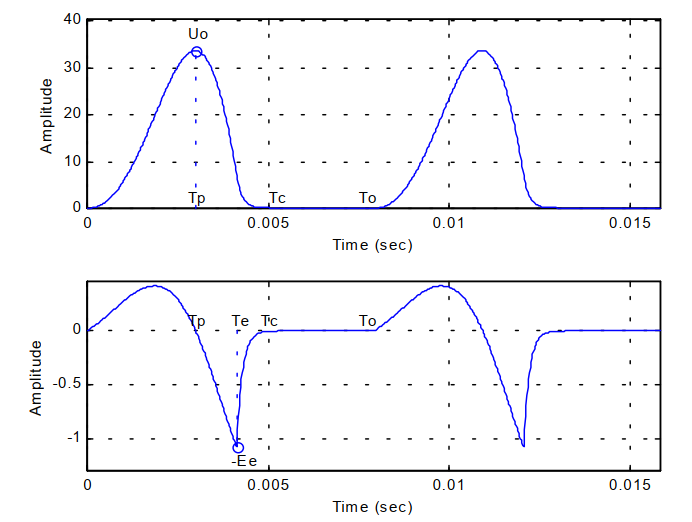

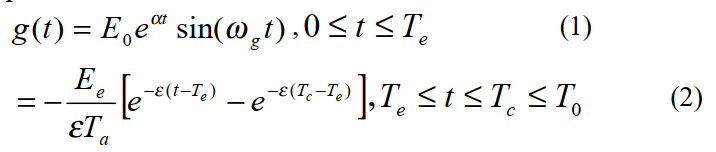

 
Bi = [1/2 1/2];
Ai = 1;
Bo = [3/2 1];

load('Abart.txt')
load('bird.txt')
load('ae-bat.txt')
load('e-bet.txt')
load('i-bit.txt')
load('ii-beet.txt')
load('o-ball.txt')
load('u-foot.txt')
load('uu-food.txt')
load('v-but.txt')

To = 0.008;
Tc = 0.005;
Tp = 0.003;
Te = 0.004;
Ta = 0.00033;
 

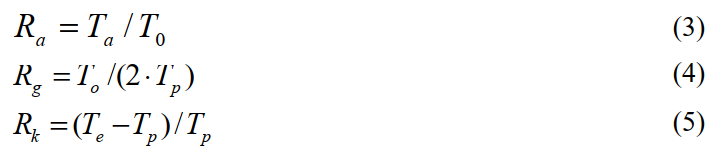

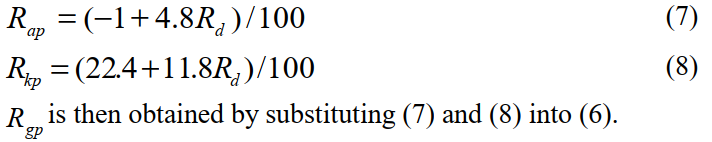

Rd = 0.98

Rd = 0.9800

Rap = (-1+4.8*Rd)/100;
Rkp = (22.4+11.8*Rd)/100;
Rgp = Rkp/(4*((0.11*Rd/(0.5+1.2*Rkp))-Rap));
To = 0.0089;
Ta = Rap*To;
Tp = To/(2*Rgp);
Te = Rkp*Tp + Tp;
Tc = min(Te + Ta*2,To);
OQ = Te/To;
% Tp < Te < Te+Ta < Tc < To
disp(['Tp = ' num2str(Tp)])

Tp = 0.0042838


disp(['Te = ' num2str(Te)])

Te = 0.0057388


disp(['Ta = ' num2str(Ta)])

Ta = 0.00032966


disp(['Te + Ta = ' num2str(Te + Ta)])

Te + Ta = 0.0060684


disp(['Tc = ' num2str(Tc)])

Tc = 0.0063981


disp(['To = ' num2str(To)])

To = 0.0089


disp(['OQ = ' num2str(OQ)])

OQ = 0.64481


The inequality $T_p < T_e < T_e+T_a < T_c < T_o$ has to be satisfied.

Tc = 0

Tc = 0

Calculate ($E_0,\alpha,  \omega_g, \epsilon$) from ($T_c, T_p, T_e, T_a$) by equations:

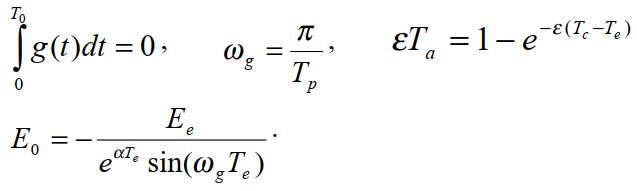

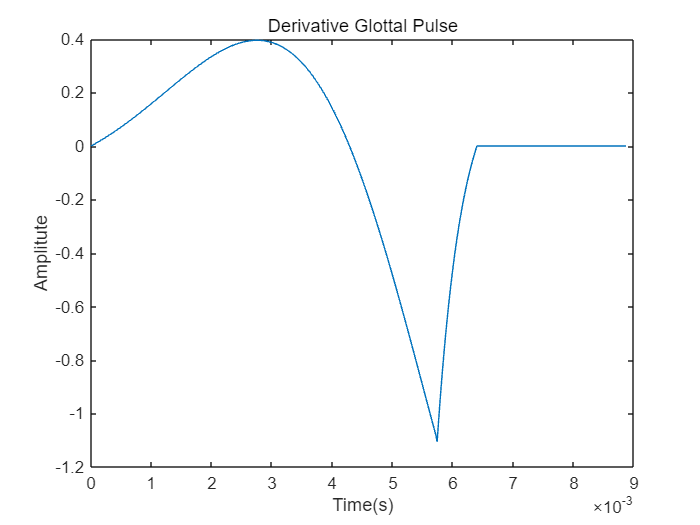

 
Ee = 1.1;
wg = pi/Tp;

% Newton iteration
e = 2000;
for i = 1:10000
    y = 1-exp(-e*(Tc-Te)) - e*Ta;
    dy = exp(-e*(Tc-Te))*(Tc-Te)-Ta;
    if abs(y) < 1e-06
        break
    else
        e = e - y/dy;
    end
end
eps = e;
G2 = -Ee/(eps*Ta)*((1-exp(-eps*(Tc-Te)))/eps - exp(-eps*(Tc-Te))*(Tc-Te));

alpha = 300;
for i = 1:10000
    y = (1/wg*(1-exp(alpha*Te)*cos(wg*Te)) + alpha./wg^2.*exp(alpha*Te)*sin(wg*Te)) - G2*(1+alpha.^2/wg^2).*(exp(alpha*Te)*sin(wg*Te))/Ee;
    dy = -Te/wg*exp(alpha*Te)*cos(wg*Te) + (1+alpha*Te)/wg^2*exp(alpha*Te)*sin(wg*Te) - G2/Ee*(exp(alpha*Te)*sin(wg*Te))*(2*alpha/wg^2 + (1+alpha^2/wg^2)*Te);
    
    if abs(y) < 1e-06
        break
    else
        alpha = alpha - y/dy;
    end
end

E0 = -Ee/(exp(alpha*Te)*sin(wg*Te));

fs = 44100;
t = Tc;
tn = 0:1/fs:t-1/fs;
g1 = E0*exp(alpha*tn(1:round(Te*fs))).*sin(wg*tn(1:round(Te*fs)));
g2 = -Ee/(eps*Ta)*(exp(-eps*(tn(round(Te*fs)+1:end)-Te)) - exp(-eps*(Tc-Te)));
g = [g1 g2];

g_p = [g zeros(1,round((To-Tc)*fs))];
n = length(g_p);
tn = [0:n-1]/fs;
fn = [0:1/n:1-1/n]*fs;
plot(tn, g_p)
xlabel('Time(s)')
ylabel('Amplitute')
title('Derivative Glottal Pulse')

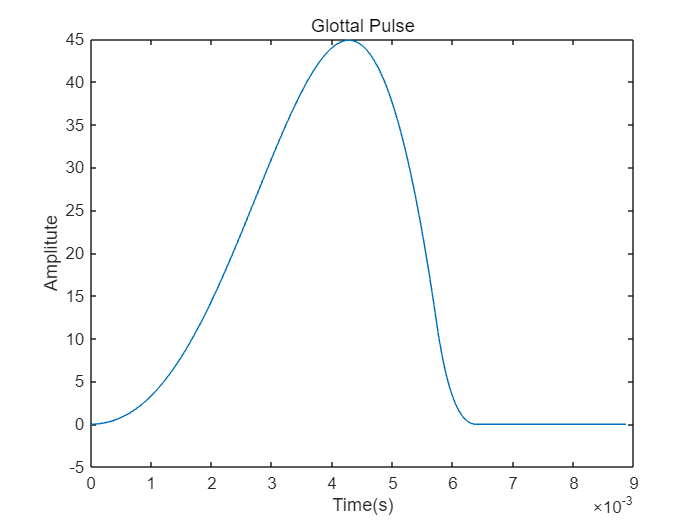

plot(tn, cumsum(g_p))
xlabel('Time(s)')
ylabel('Amplitute')
title('Glottal Pulse')

% plot(fn, abs(fft(g_p)))
% xlim([0 5e+03])

 
Ra = Ta/To;
Rg = To/(2*Tp);
Rk = (Te - Tp)/Tp;
Rd = (1/0.11)*(0.5+1.2*Rk)*(Rk/(4*Rg)+Ra);
disp(['Rd = ' num2str(Rd)])

Rd = 0.98


y_vowel = []; 

 
func = "exponential up"

func = "exponential up"

f = 256

f = 256

ni = 30

ni = 30

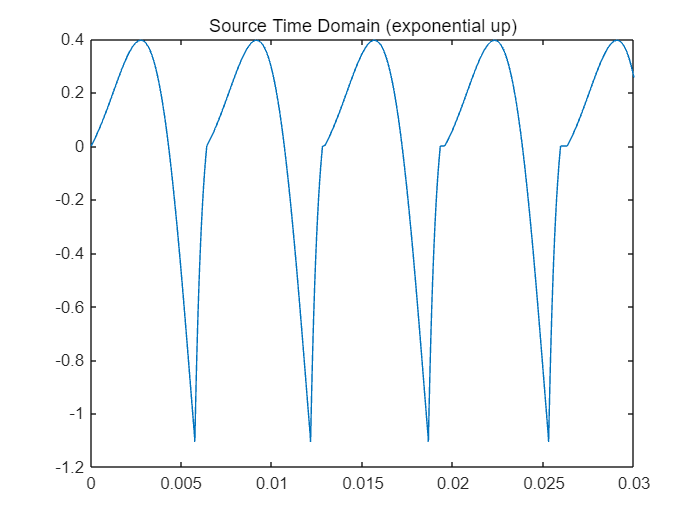

switch func
    case "constant"
        g_p = [g zeros(1,round((To-Tc)*fs))];
        g_sq = [];
        for i = 1:ni
            g_sq = [g_sq g_p];
        end
    case "random"
        g_sq = [];
        for i = 1:ni
            Tr = rand*(To-Tc)*2;
            g_p = [g zeros(1,round(Tr*fs))];
            g_sq = [g_sq g_p];
        end
    case "sine"
        g_sq = [];
        Tsin = (To-Tc)*2*abs(sin(2*pi*f*[1:ni]/fs));
        for i = 1:ni
            g_p = [g zeros(1,round(Tsin(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "cosine"
        g_sq = [];
        Tcos = (To-Tc)*2*abs(cos(2*pi*f*[1:ni]/fs));
        for i = 1:ni
            g_p = [g zeros(1,round(Tcos(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "linear up"
        g_sq = [];
        Tlu = linspace(0,1,ni)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlu(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "linear down"
        g_sq = [];
        Tlu = linspace(1,0,ni)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlu(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "exponential up"
        g_sq = [];
        a = log(2)/(ni-1);
        Tep = (exp(a*[0:ni-1])-1)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tep(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "exponential down"
        g_sq = [];
        a = log(0.01)/(ni-1);
        Tep = (exp(a*[0:ni-1]))*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tep(i)*fs))];
            g_sq = [g_sq g_p];
        end
    case "log"
        g_sq = [];
        Tlog = log(linspace(1,exp(1),ni))*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlog(i)*fs))];
            g_sq = [g_sq g_p];
        end
end

src_new = g_sq;
n = length(src_new);
tn = [0:n-1]/fs;
fn = [0:1/n:1-1/n]*fs;
figure
plot(tn, src_new)
xlim([0 0.03])
title('Source Time Domain ('+func+')')

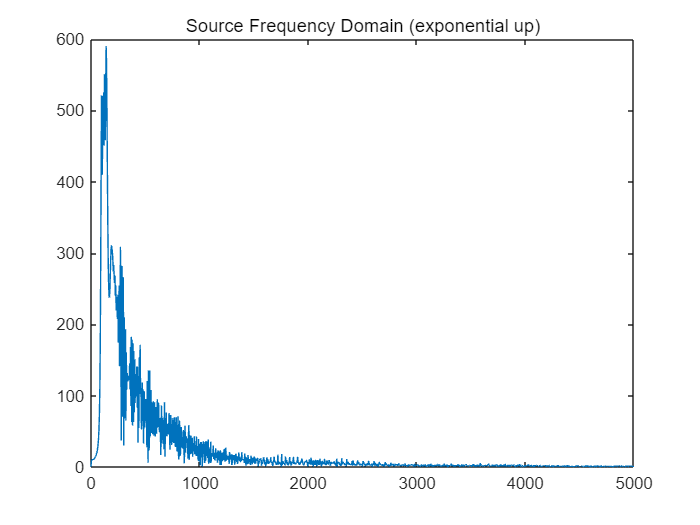

figure
plot(fn, abs(fft(src_new)))
xlim([0 5e+03])
title('Source Frequency Domain ('+func+')')

 
soundsc(src_new,fs)

 

vowel = "3-bird"

vowel = "3-bird"

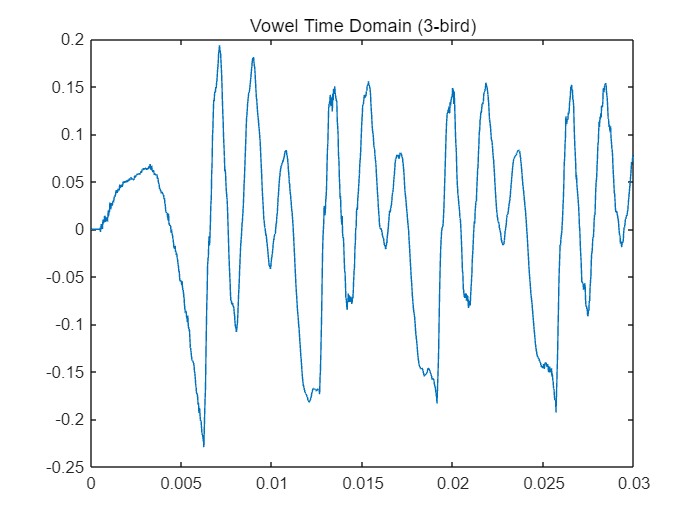

switch vowel
    case "A-bart"
        S = Abart';
    case "3-bird"
        S = bird';
    case "ae-bat"
        S = ae_bat';
    case "e-bet"
        S = e_bet';
    case "i-bit"
        S = i_bit';
    case "ii-beet"
        S = ii_beet';
    case "o-ball"
        S = o_ball';
    case "u-foot"
        S = u_foot';
    case "uu-food"
        S = uu_food';
    case "v-but"
        S = v_but';
end
N = length(S);
k = (S(1:end-1) - S(2:end)) ./ (S(1:end-1) + S(2:end));
ins = zeros(2,N);
outs = zeros(2,N);
uend = 0;
lend = 0;
R0 = 0.4;
RL = -0.1;
y = zeros(1,n);
zf = 0;
zfy = 0;
for i = 1:n
    uend = outs(1,N);
    lend = outs(2,1);
    
    outs(1,2:N) = ins(1,1:N-1).*(1+k) - k.*ins(2,2:N);
    outs(2,1:N-1) = ins(2,2:N).*(1-k) + k.*ins(1,1:N-1);
    outs(1,1) = lend*R0 + src_new(i);
%     outs(2,N) = uend*RL;
    [z,zf] = filter(Bi,Ai,uend,zf);
    outs(2,N) = -z;
    ins = outs;
    [y(i),zfy] = filter(Bo,Ai,uend,zfy);
    y(i) = uend;
end
amp = [linspace(0,1,round(n*0.1)) ones(1,round(n*0.7)) linspace(1,0,n-round(n*0.1)-round(n*0.7))];
y_amp = y.*amp/max(y)*0.99;
y_vowel = [y_vowel y_amp];

figure
plot(tn, y)
xlim([0 0.03])
title('Vowel Time Domain ('+vowel+')')

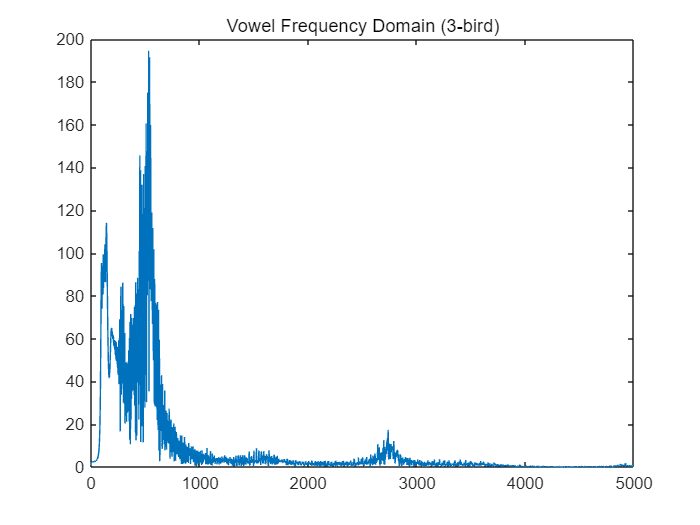

figure
plot(fn, abs(fft(y)))
xlim([0 5e+03])
title('Vowel Frequency Domain ('+vowel+')')

 
soundsc(y_amp,fs)

 
soundsc(y_vowel,fs)

Add Gaussian noise to the glottal source.

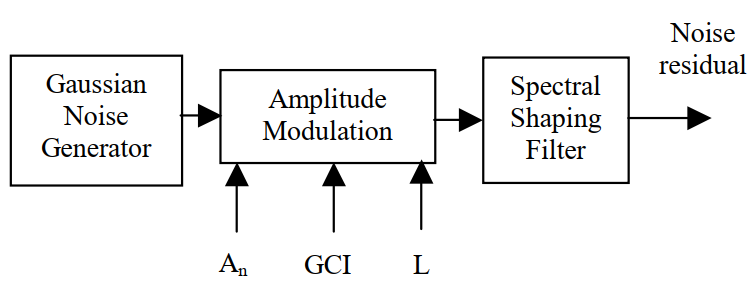

func = "exponential up"

func = "exponential up"

f = 553

f = 553

ni = 48

ni = 48

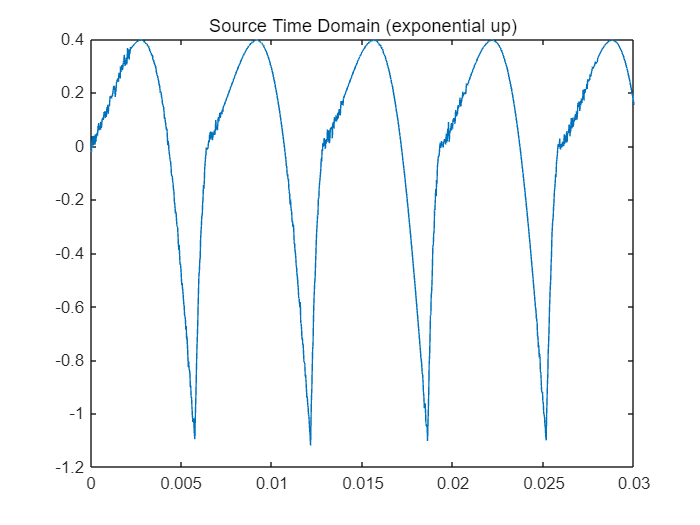

 
Gaussian = randn(1,round(n*1.5));
ng = length(g);

switch func
    case "constant"
        g_p = [g zeros(1,round((To-Tc)*fs))];
        g_sq = [];
        ngp = length(g_p);
        nslc = ngp-ng;
        for i = 1:ni
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(20);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "random"
        g_sq = [];
        for i = 1:ni
            Tr = rand*(To-Tc)*2;
            g_p = [g zeros(1,round(Tr*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "sine"
        g_sq = [];
        Tsin = (To-Tc)*2*abs(sin(2*pi*f*[1:ni]/fs));
        for i = 1:ni
            g_p = [g zeros(1,round(Tsin(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "cosine"
        g_sq = [];
        Tcos = (To-Tc)*2*abs(cos(2*pi*f*[1:ni]/fs));
        for i = 1:ni
            g_p = [g zeros(1,round(Tcos(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "linear up"
        g_sq = [];
        Tlu = linspace(0,1,ni)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlu(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "linear down"
        g_sq = [];
        Tlu = linspace(1,0,ni)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlu(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "exponential up"
        g_sq = [];
        a = log(2)/(ni-1);
        Tep = (exp(a*[0:ni-1])-1)*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tep(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "exponential down"
        g_sq = [];
        a = log(0.01)/(ni-1);
        Tep = (exp(a*[0:ni-1]))*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tep(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if nsq+ng-round(L/2)+lag > 1 && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
    case "log"
        g_sq = [];
        Tlog = log(linspace(1,exp(1),ni))*(To-Tc)*2;
        for i = 1:ni
            g_p = [g zeros(1,round(Tlog(i)*fs))];
            ngp = length(g_p);
            nslc = ngp-ng;
            L = randi([ngp,max(nslc,ng)*2]);
            hanning = hann(L)';
            lag = randi(10);
            nsq = length(g_sq);
            if (nsq+ng-round(L/2)+lag > 1) && (nsq+ng-round(L/2)+lag+L-1 < length(Gaussian))
                 Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1) = Gaussian(nsq+ng-round(L/2)+lag:nsq+ng-round(L/2)+lag+L-1).*hanning;
            end
            g_sq = [g_sq g_p];
        end
        
end
noise = filter(1,[1 -0.9],Gaussian);
noise = diff(noise);
g_sqnoise = g_sq + 0.015*noise(1:length(g_sq));

src_new = g_sqnoise;
n = length(src_new);
tn = [0:n-1]/fs;
fn = [0:1/n:1-1/n]*fs;
figure
plot(tn, src_new)
xlim([0 0.03])
title('Source Time Domain ('+func+')')

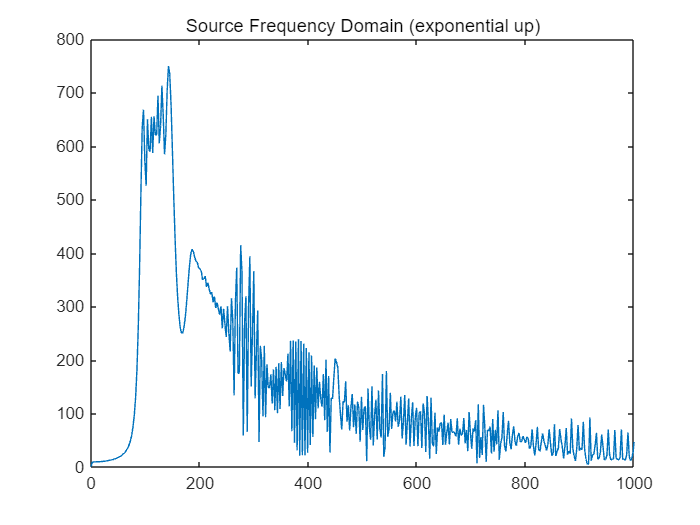

figure
plot(fn, abs(fft(src_new)))
xlim([0 1e+03])
title('Source Frequency Domain ('+func+')')

 
vowel = "A-bart"

vowel = "A-bart"

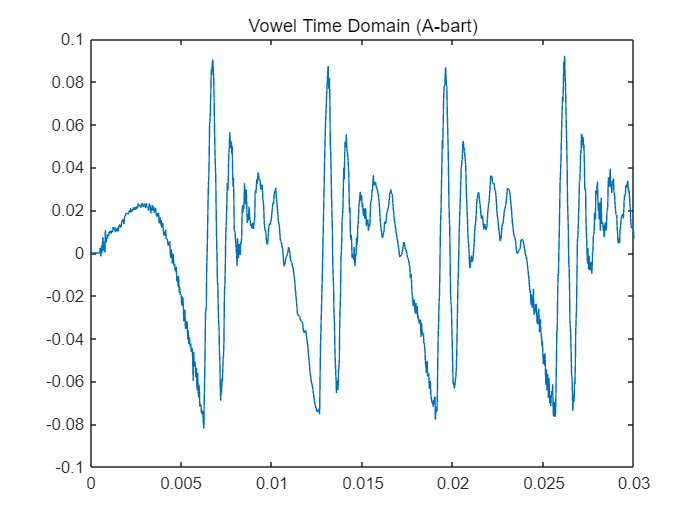

switch vowel
    case "A-bart"
        S = Abart';
    case "3-bird"
        S = bird';
    case "ae-bat"
        S = ae_bat';
    case "e-bet"
        S = e_bet';
    case "i-bit"
        S = i_bit';
    case "ii-beet"
        S = ii_beet';
    case "o-ball"
        S = o_ball';
    case "u-foot"
        S = u_foot';
    case "uu-food"
        S = uu_food';
    case "v-but"
        S = v_but';
end
N = length(S);
k = (S(1:end-1) - S(2:end)) ./ (S(1:end-1) + S(2:end));
ins = zeros(2,N);
outs = zeros(2,N);
uend = 0;
lend = 0;
R0 = 0.4;
RL = -0.1;
yns = zeros(1,n);
zf = 0;
zfy = 0;
for i = 1:n
    uend = outs(1,N);
    lend = outs(2,1);
    
    outs(1,2:N) = ins(1,1:N-1).*(1+k) - k.*ins(2,2:N);
    outs(2,1:N-1) = ins(2,2:N).*(1-k) + k.*ins(1,1:N-1);
    outs(1,1) = lend*R0 + src_new(i);
%     outs(2,N) = uend*RL;
    [z,zf] = filter(Bi,Ai,uend,zf);
    outs(2,N) = -z;
    ins = outs;
    [yns(i),zfy] = filter(Bo,Ai,uend,zfy);
    yns(i) = uend;
end
amp = [linspace(0,1,round(n*0.1)) ones(1,round(n*0.7)) linspace(1,0,n-round(n*0.1)-round(n*0.7))];
yns_amp = yns.*amp/max(yns)*0.99;
y_vowel = [y_vowel yns_amp];

figure
plot(tn, yns)
xlim([0 0.03])
title('Vowel Time Domain ('+vowel+')')

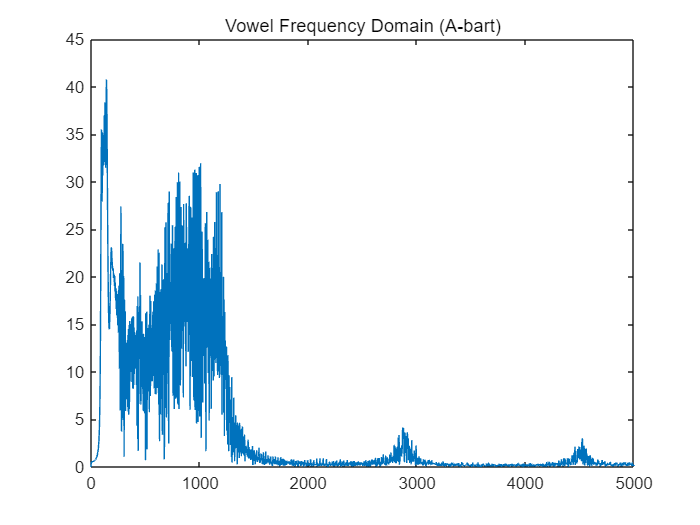

figure
plot(fn, abs(fft(yns)))
xlim([0 5e+03])
title('Vowel Frequency Domain ('+vowel+')')

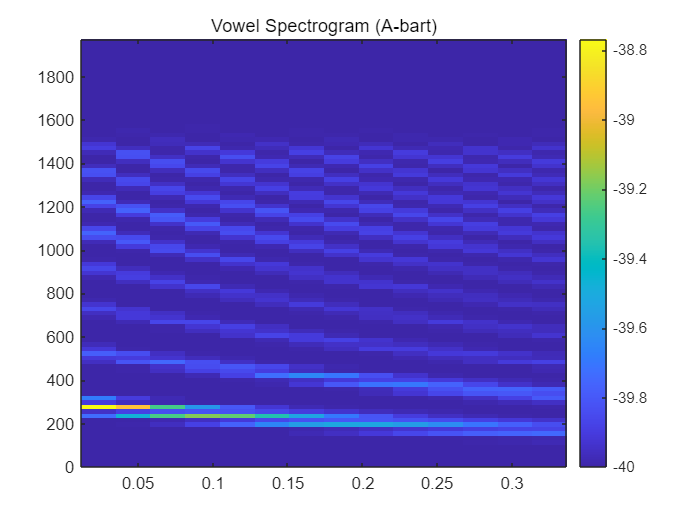

window = 2048;
[S,fc,t1] = melSpectrogram(yns',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',96, ...
                   'FrequencyRange',[0,2000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Vowel Spectrogram ('+vowel+')')
colorbar

 
soundsc(yns_amp,fs)

 
soundsc(y_vowel,fs)

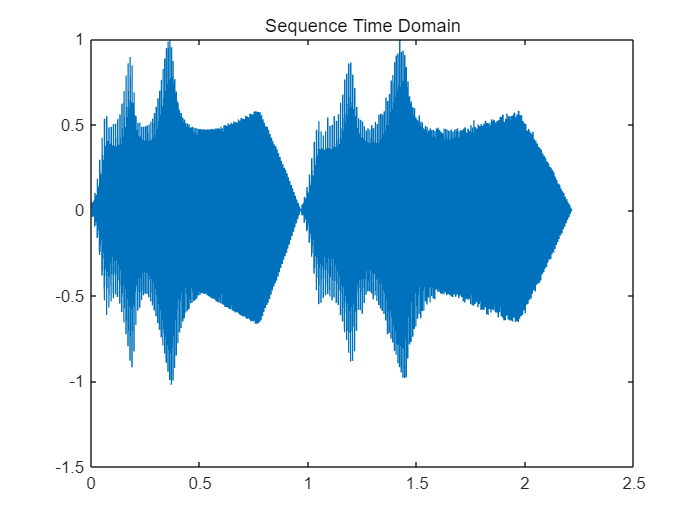

 
n_all = length(y_vowel);
tn_all = [0:n_all-1]/fs;
figure
plot(tn_all, y_vowel)
title('Sequence Time Domain')

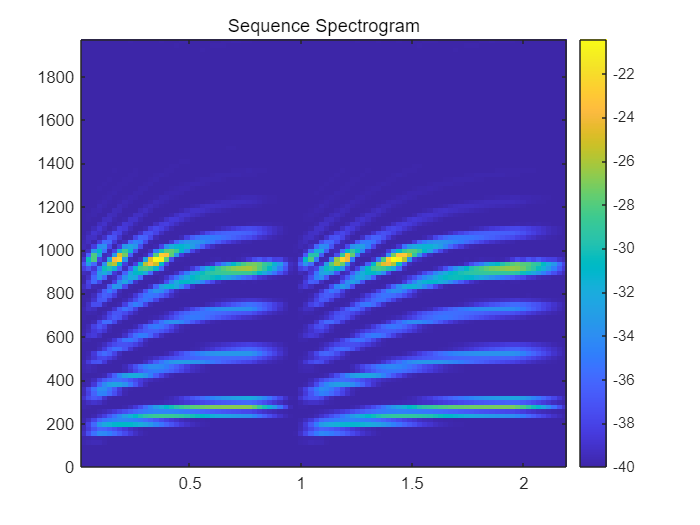


window = 2048;
[S,fc,t1] = melSpectrogram(y_vowel',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',96, ...
                   'FrequencyRange',[0,2000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Sequence Spectrogram')
colorbar

y_vowel = []; 

LPC estimation and synthesis

[vocal,fs] = audioread('verse1_vocal.wav')

vocal =     0.0065    0.0065
    0.0101    0.0102
   -0.0010   -0.0010
   -0.0115   -0.0114
   -0.0079   -0.0079
    0.0038    0.0039
    0.0082    0.0083
    0.0006    0.0006
   -0.0078   -0.0077
   -0.0057   -0.0056


fs = 44100

% input = yns_amp;
input = vocal(1:2*fs);
nn = length(input);
L = round(0.012*fs); % half length of hann window
number = ceil(nn/L);
if mod(number,2) == 0
    number = number + 1;
end
y_wave = [input zeros(1, number*L - nn+5)];
order = 15; % lpc order
n_hann = floor(length(y_wave)/L)-1;
Coef = zeros(n_hann,order+1);
Res = zeros(1,length(y_wave));
Residual_mx = zeros(n_hann,2*L);
for i = 1:n_hann
    sample = y_wave((i-1)*L+1:(i+1)*L);
    new_sp = sample.*hann(2*L)';
    cf = lpc(new_sp,order);
    Coef(i,:) = cf;
    y_ = filter([0 -cf(2:end)],1,new_sp);
    residual = new_sp - y_;
    Res((i-1)*L+1:(i+1)*L) = Res((i-1)*L+1:(i+1)*L) + residual;
    Residual_mx(i,:) = residual;
end

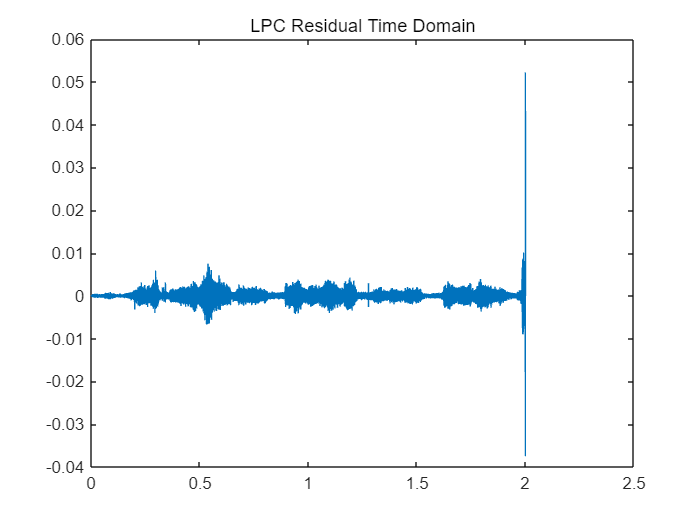

n = length(Res);
tn = [0:n-1]/fs;
fn = [0:1/n:1-1/n]*fs;
figure
plot(tn, Res)
title('LPC Residual Time Domain')

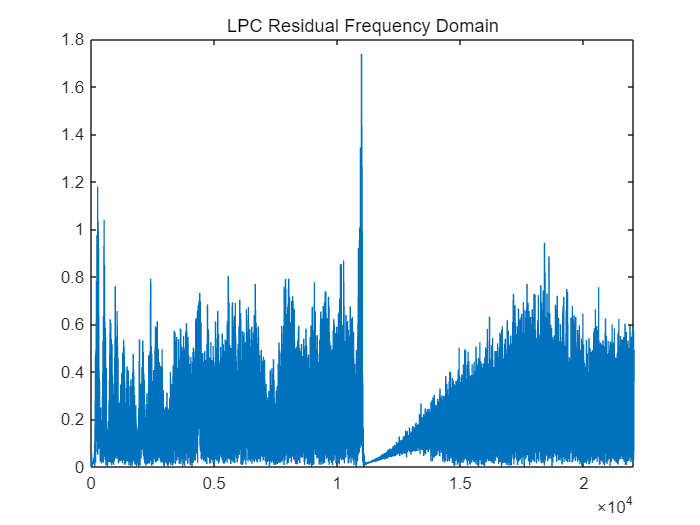

figure
plot(fn, abs(fft(Res)))
xlim([0 fs/2])
title('LPC Residual Frequency Domain')

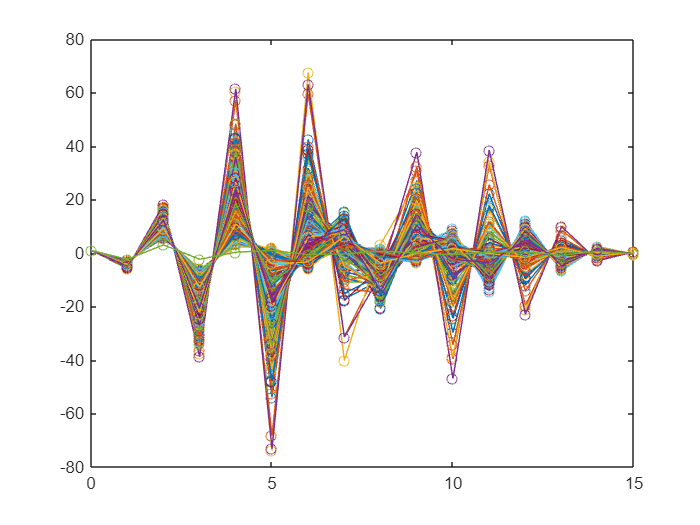

x = 0:order;
for i = 1:n_hann
    plot(x,Coef(i,:),'Marker',"o")
    hold on
end
hold off

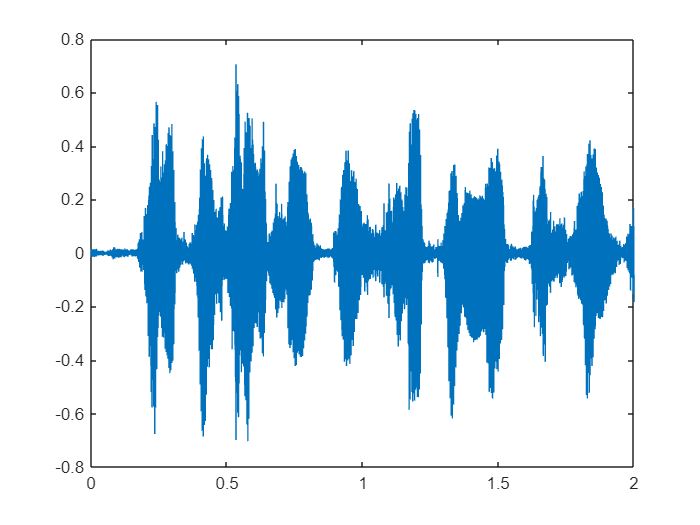

Reconstru = zeros(1,length(y_wave));
for i = 1:n_hann
    yy = filter(1,Coef(i,:),Residual_mx(i,:));
    Reconstru((i-1)*L+1:(i+1)*L) = Reconstru((i-1)*L+1:(i+1)*L) + yy;
end
Reconstru = Reconstru(1:nn);

n = length(input);
tn = [0:n-1]/fs;
fn = [0:1/n:1-1/n]*fs;

figure
plot(tn,input)

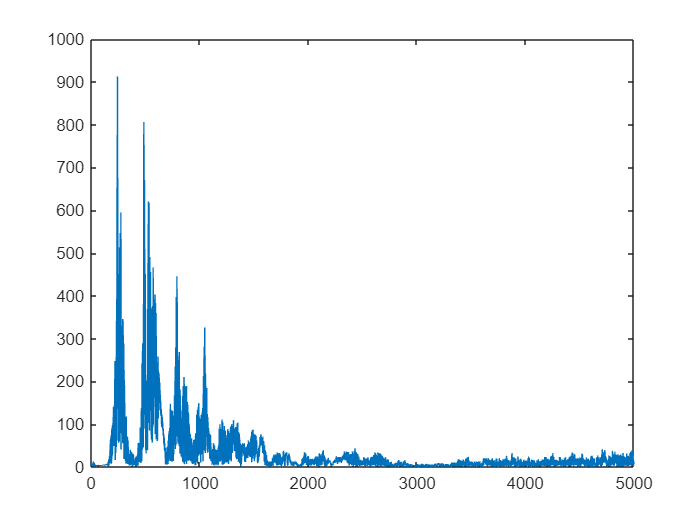

figure
plot(fn, abs(fft(input)))
xlim([0 5e+03])

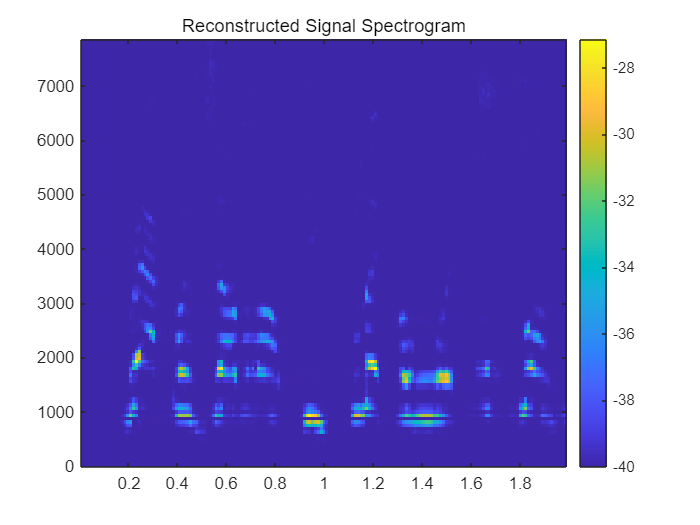

figure
window = 1024;
[S,fc,t1] = melSpectrogram(input',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Reconstructed Signal Spectrogram')
colorbar

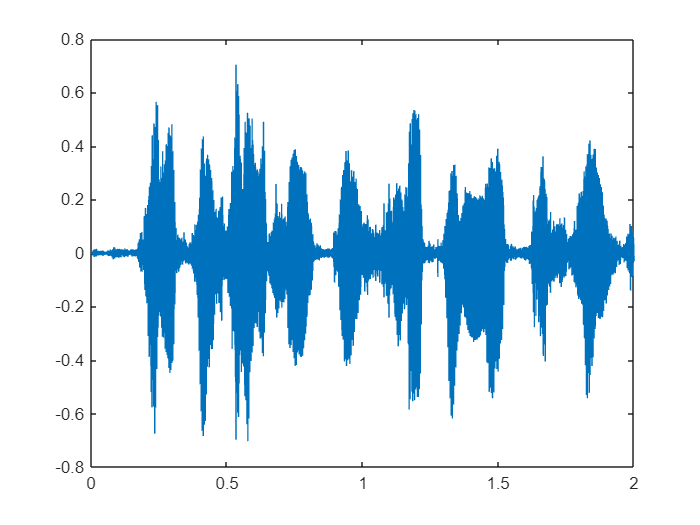


figure
plot(tn,Reconstru)

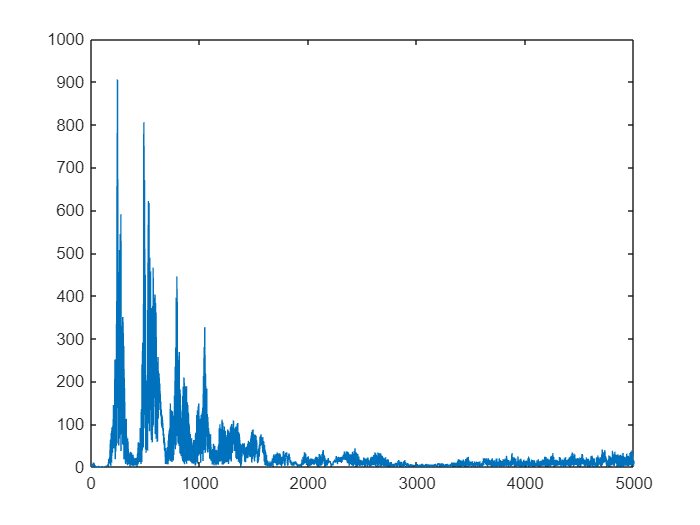

figure
plot(fn, abs(fft(Reconstru)))
xlim([0 5e+03])

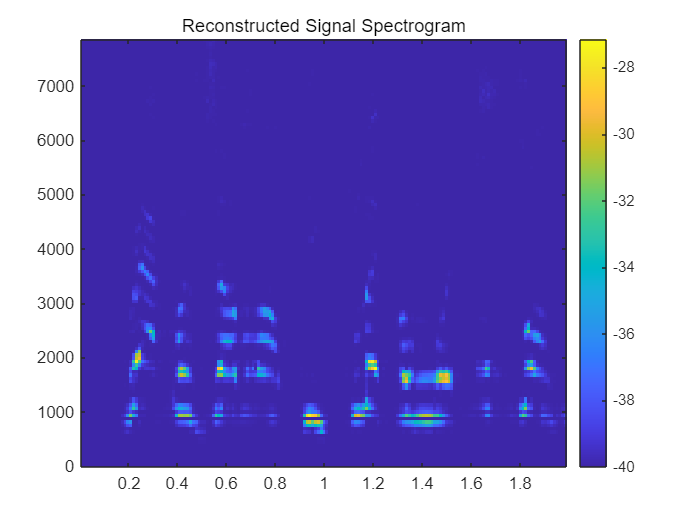

figure
window = 1024;
[S,fc,t1] = melSpectrogram(Reconstru',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Reconstructed Signal Spectrogram')
colorbar

soundsc(Reconstru,fs)

soundsc(input,fs)

yy = filter(1,Coef(11,:),Res)

yy =          0    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001


soundsc(yy,fs)

soundsc(Res,fs)

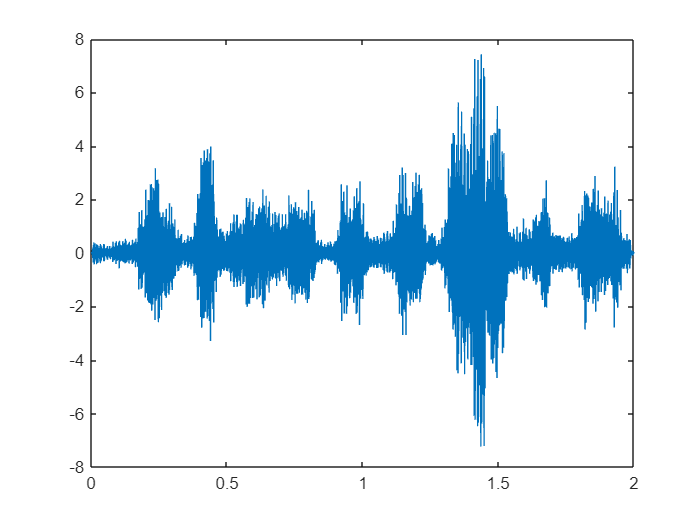

glt = [g_sqnoise zeros(1,length(Res)-length(g_sqnoise))];
Glt_mx = zeros(n_hann,2*L);
for i = 1:n_hann
    sample = glt((i-1)*L+1:(i+1)*L);
    new_sp = sample.*hann(2*L)';
    Glt_mx(i,:) = new_sp;
end
Reconstru_glt = zeros(1,length(y_wave));
for i = 1:n_hann
    yy = filter(1,Coef(i,:),Residual_mx(n_hann,:)); % Residual_mx(randi(n_hann)); Glt_mx;
                                                 % [1 zeros(1,2*L-1)]
    
    Reconstru_glt((i-1)*L+1:(i+1)*L) = Reconstru_glt((i-1)*L+1:(i+1)*L) + yy;
end
Reconstru_glt = Reconstru_glt(1:nn);

figure
plot(tn,Reconstru_glt)

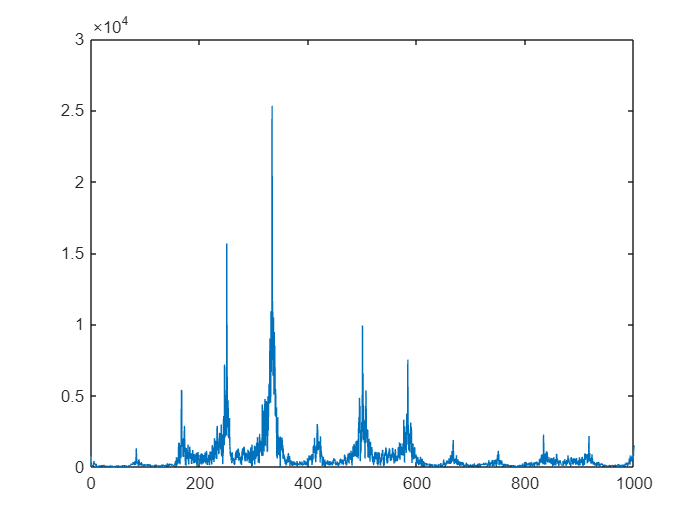

figure
plot(fn, abs(fft(Reconstru_glt)))
xlim([0 1e+03])

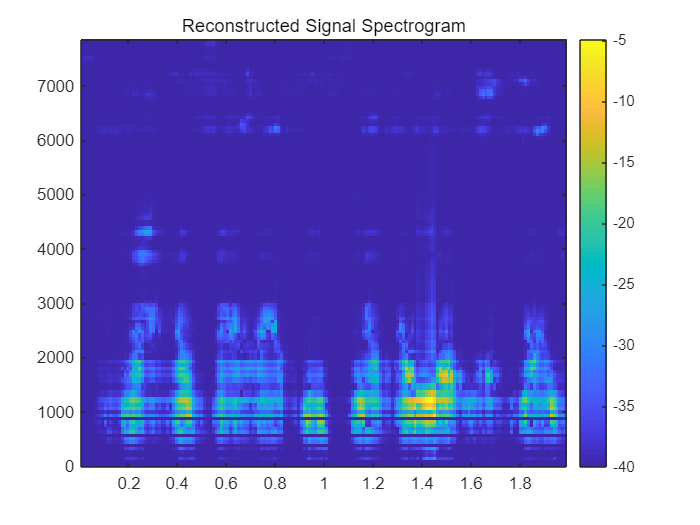

figure
window = 1024;
[S,fc,t1] = melSpectrogram(Reconstru_glt',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Reconstructed Signal Spectrogram')
colorbar

soundsc(Reconstru_glt,fs)

soundsc(g_sqnoise,fs)